dt = datetime("now");
dt.Format = 'yyyyMMddHHmm';
outputfile = 'generate_grayscale_matrices_output/output_log_' + string(dt) + '.txt'

outputfile = "generate_grayscale_matrices_output/output_log_202503042147.txt"


diary(outputfile); % Start logging to a file
diary on; % Enable logging

% To try to formulate a solution that allows each row of the CCM have
% unique components (a11, a12, a13 are unique instead of identical) we
% eliminate using identical scalar value rows (the patch method) that
% correspond to R1 R2 R3 (different R values of each patch.

% New method has 3 different scalar values map to the same R value in each
% row. This is done by setting an R value (R1=50, etc), and then
% caluclating any scalar value with that R value (online calculator) so the 
% G, B values are arbitrary.

% Therefore, we need 3 grayscale matrices to calculate each row of CCM
% coefficients.
%   [ s11 s12 s13 ]   [ a11 ]     [ R1 ]
%   [ s21 s22 s23 ] * [ a12 ]  =  [ R2 ]
%   [ s31 s32 s33 ]   [ a13 ]     [ R3 ]

b_redMatrix =   [255 255 255]';
b_greenMatrix = [255 255 255]';
b_blueMatrix =  [255 255 255]';

disp('b_redMatrix: ');

b_redMatrix: 


disp(b_redMatrix);

   200
   200
   200



disp('b_greenMatrix: ');

b_greenMatrix: 


disp(b_greenMatrix);

   200
   200
   200



disp('b_blueMatrix: ');

b_blueMatrix: 


disp(b_blueMatrix);

   200
   200
   200




S_grayscaleMatrix_red = generate_grayscale_matrix(b_redMatrix, 'r');
S_grayscaleMatrix_green = generate_grayscale_matrix(b_greenMatrix, 'g');
S_grayscaleMatrix_blue = generate_grayscale_matrix(b_blueMatrix, 'b');

disp('S_grayscaleMatrix_red: ');

S_grayscaleMatrix_red: 


disp(S_grayscaleMatrix_red);

  131.7580   63.8920   65.3110
  131.7750   66.4680   63.5330
  133.6330   63.5330   63.8750



disp('S_grayscaleMatrix_green: ');

S_grayscaleMatrix_green: 


disp(S_grayscaleMatrix_green);

  118.1120  158.9990  119.0520
  119.5080  161.4060  121.5300
  118.1120  160.9070  119.4650



disp('S_grayscaleMatrix_blue: ');

S_grayscaleMatrix_blue: 


disp(S_grayscaleMatrix_blue);

   28.4260   28.1050  116.7270
   24.2840   25.7680  116.0960
   25.7460   26.6540  116.1400




c_redMatrix = S_grayscaleMatrix_red\b_redMatrix;
% c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)
c_greenMatrix = S_grayscaleMatrix_green\b_greenMatrix;
c_blueMatrix = S_grayscaleMatrix_blue\b_blueMatrix;

colorCorrectionMatrix = [
    c_redMatrix'; % Red channel mapping
    c_greenMatrix'; % Green channel mapping
    c_blueMatrix'; % Blue channel mapping
    ];

disp('calculated color correction matrix: ');

calculated color correction matrix: 


disp(colorCorrectionMatrix);

    0.7895    0.6024    0.8803
    3.4639    0.5349   -2.4710
   -2.4409    3.9606    1.3542




disp('CCM inverse: ');

CCM inverse: 


disp(inv(colorCorrectionMatrix));

    0.4707    0.1196   -0.0877
    0.0600    0.1441    0.2239
    0.6728   -0.2059   -0.0745



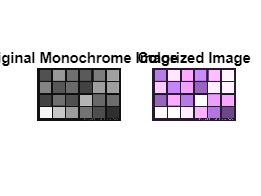

colorized image saved to colorized_images/colorized_image_20250304214740.png



returned_img = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix);

diary off;

functions definitions start

function gray_matrix = generate_grayscale_matrix(b_vector, color)

    switch color
        case 'r'
            component = 1;
        case 'g'
            component = 2;
        case 'b'
            component = 3;
    end

    % initialize 3x3 mat
    gray_matrix = zeros(3, 3);
    
    % iterate over matrix rows
    % flag = false;
    for row = 1:3
        % get fixed color channel value for this row
        val = b_vector(row);
        % iterate over columns
        for col = 1:3
            if col == component
                flag = true;
            else
                flag = false;
            end
            gray_matrix(row, col) = calc_random_gray(val, color, flag);
        end
    end
end

% calculate scalar given one of the component values 
% e.g. if value is a num, and color=='r' then calc gray using (R=value, G=random1, B=random2)
function scalar = calc_random_gray(value, color, flag)  

    if flag
        lower = 100;
        upper = 110;
    else
        lower = 0;
        upper = 10;
    end

    % calc random1 and random2   % (old version:) between 0-255
    random1 = randi([lower, upper]);
    random2 = randi([lower, upper]);

    % calc weighted sum with given color value
    % switch lower(color)  % was giving an error for no reason? march 4
    % 2025 edits, but not prior.
    switch color
        case 'r'
            scalar = 0.299*2*value + 0.587*random1 + 0.114*5*random2;
        case 'g'
            scalar = 0.299*2*random1 + 0.587*value + 0.114*5*random2;
        case 'b'
            scalar = 0.299*2*random1 + 0.587*random2 + 0.114*5*value;
    end
end

function rgbImage = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)
% Read the monochrome image.
initial_rgbImage = imread('images/Reflective-color-chart-reference-COLOR.png', 'png');
grayImage = rgb2gray(initial_rgbImage);

% Define a color correction matrix for RGB color mapping.
% Simple example below.
colorCorrectionMatrix = [
    c_redMatrix'; % Red channel mapping
    c_greenMatrix'; % Green channel mapping
    c_blueMatrix'; % Blue channel mapping
    ];

% Get image dimensions.
[rows, cols] = size(grayImage);

% Initialize RGB image matrix.
% rgbImage = zeros(rows, cols, 3);
rgbImage = initial_rgbImage; % Hijacks format used by imread.

% Apply color correction by looping over each pixel.
for i = 1:rows
    for j = 1:cols
        % Get grayscale value of current pixel.
        grayValue = double(grayImage(i, j)); 

        % Apply color correction matrix to map grayscale value to RGB
        % values.
        rgbValue = colorCorrectionMatrix * [grayValue; grayValue; grayValue];
        
        % Store RBG values in the output image matrix.
        rgbImage(i, j, :) = uint8(rgbValue); % ':' is the rgb vector
    end
end

% Display the original monochrome image and the transformed color image.
figure;
subplot(1, 2, 1);
imshow(grayImage);
title('Original Monochrome Image');
% rgbImage

subplot(1, 2, 2);
imshow(rgbImage);
title('Colorized Image');

% Save the colorized image to a new file.
dt = datetime("now");
dt.Format = 'yyyyMMddHHmmSS';
filename = 'colorized_images/colorized_image_' + string(dt) + '.png';
imwrite(rgbImage, filename);

fprintf('colorized image saved to %s\n', filename);

end

function definitions end